s=tf('s');
Wp=[(0.57*s+0.95)/(2*s+0.024) 0 0 0 0;...
     0 0.9 0 0 0;...
     0 0 0.15 0 0;
     0 0 0 (0.242*s+0.22)/(s+1) 0;...
     0 0 0 0 (1.08*s+1.8)/(4*s+0.048)];
Wu=(0.06*s+0.04)/(0.0024*s+1)*eye(2);
Wn=[0.5*s+1 0;0 s+2]/(0.001*s+1);
int1=1/(s+10^-6);


G=ss(A,B,eye(4),0);
Wp = Wp(1:4, 1:4);
systemnames  = 'G Wp Wu int1';
inputvar     = '[r{4}; u{2}]';
outputvar    = '[Wp; r(1:2)-G(1:2); r(3:4)-G(3:4); int1]';
input_to_G   = '[u]';
input_to_int1 ='[r(1)-G(1)]';
input_to_Wp  = '[r-G]';
input_to_Wu  = '[u]';
% input_to_Wn =  '[n]';

P = minreal(sysic);

2 states removed.



G=ss(A,B,eye(4),0);
systemnames  = 'G  int1';
inputvar     = '[r{4}; u{2}]';
outputvar    = '[G;u; r(1:2)-G(1:2); r(3:4)-G(3:4); int1]';
input_to_G   = '[u]';
input_to_int1 ='[r(1)-G(1)]';
% input_to_Wp  = '[r-G; int1]';
% input_to_Wu  = '[u]';
% input_to_Wn =  '[n]';

Psim = minreal(sysic);

k4 = 2.8141;
k3 = 1.0995;
k2 = 34.1896;
k1 = 0.8351;
ki = 0.4473;
Kp = -[k1 k2 k3 k4 ki;k1 k2 k3 k4 ki]

Kp =    -0.8351  -34.1896   -1.0995   -2.8141   -0.4473
   -0.8351  -34.1896   -1.0995   -2.8141   -0.4473


w = logspace(-2,2,100);
Proba = lft(P,K)

Proba =

  Uncertain continuous-time state-space model with 4 outputs, 4 inputs, 7 states.
  The model uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [5e-05,0.0002], 1 occurrences

Type "Proba.NominalValue" to see the nominal value, "get(Proba)" to see all properties, and "Proba.Uncertainty" to interact with the uncertain elements.




isstable(Proba.NominalValue)

ans = logical
   1


kritmin = 1e6;
K = Kp;
Kmin = K;
for k1i = linspace(0.5*k1,1.5*k1,4)   
  for k2i = linspace(0.5*k2,1.5*k2,4) 
    for k3i = linspace(0.5*k3,1.5*k3,4)
      for k4i = linspace(0.5*k4,1.5*k4,4)
        for kii = linspace(0.5*ki,1.5*ki,4)
            
            K = -[k1i k2i k3i k4i kii;k1i k2i k3i k4i kii];
            Proba = lft(P.NominalValue,K);
            sig = sigma(Proba,w);
            krit= max(sig(1,:));
            if(krit < kritmin && isstable(Proba)) 
                Kmin = K;
                disp(krit)
                kritmin = krit;
            end
        end 
      end
    end
  end  
end

   37.2096

   31.2656

   31.2579

   21.6462

   16.2549

   15.4153

   13.8259

   12.8102

   12.1320



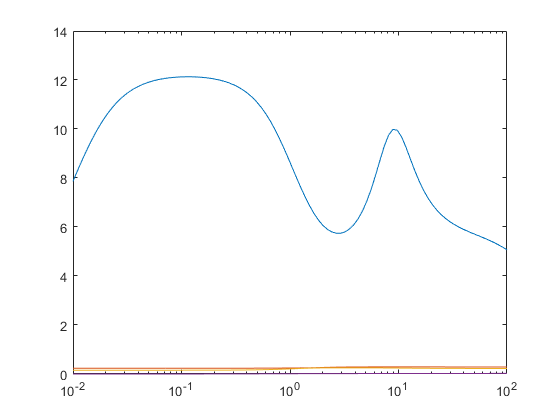


Proba = lft(P.NominalValue,Kmin);
sig = sigma(Proba,w);
figure;
semilogx(w,sig)

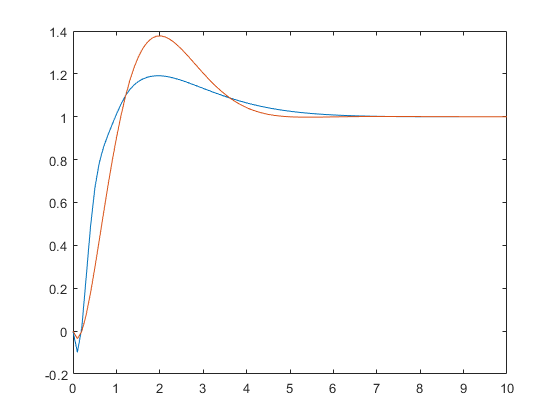

PsimCL = lft(Psim,Kmin);
PsimCL2 = lft(Psim,Kp);
r = zeros(4,100);
r(1,:) = 1;
t = linspace(0,10,100);

[y1,t] = lsim(PsimCL.NominalValue, r, t);
[y2,t] = lsim(PsimCL2.NominalValue, r, t);
figure;
plot(t,y1(:,1),t,y2(:,1))

Gmu = lft(P,Kmin)

Gmu =

  Uncertain continuous-time state-space model with 4 outputs, 4 inputs, 7 states.
  The model uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [5e-05,0.0002], 1 occurrences

Type "Gmu.NominalValue" to see the nominal value, "get(Gmu)" to see all properties, and "Gmu.Uncertainty" to interact with the uncertain elements.




[Nmu, Del] = lftdata(Gmu);

Nrsmu = tf(Nmu);

Nrsmu = Nrsmu(1:2,1:2);

bndrsmu = mussv(frd(Nrsmu,w),[-1 0; -1 0]);

Points completed: 100/100




blkstr = [-1 0; -1 0; 4 4];
bndmu = mussv(frd(Nmu,w),blkstr);

Points completed: 100/100


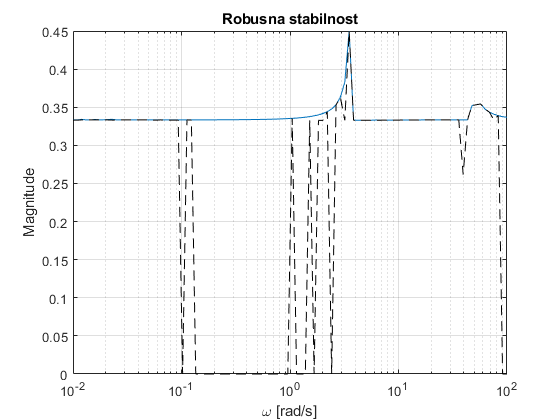


figure;
semilogx(w, squeeze(bndrsmu.ResponseData(1,1,:)))
hold on
semilogx(w, squeeze(bndrsmu.ResponseData(1,2,:)),'k--')
xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Robusna stabilnost")
grid on

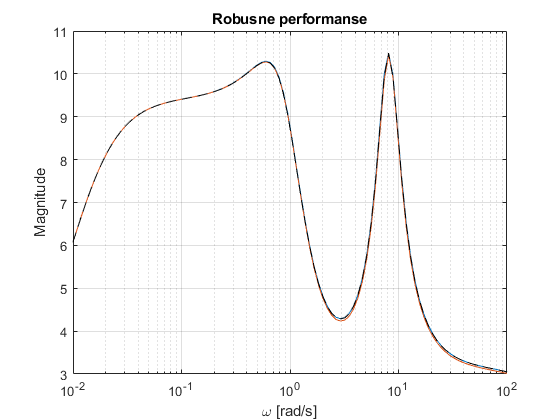


figure;
semilogx(w, squeeze(bndmu.ResponseData(1,1,:)))
hold on
semilogx(w, sig(1,:))
semilogx(w, squeeze(bndmu.ResponseData(1,2,:)),'k--')
xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Robusne performanse")
grid on